MATLAB code to compute the filled Julia set for $\varphi (z) = z^2 - 1.25$

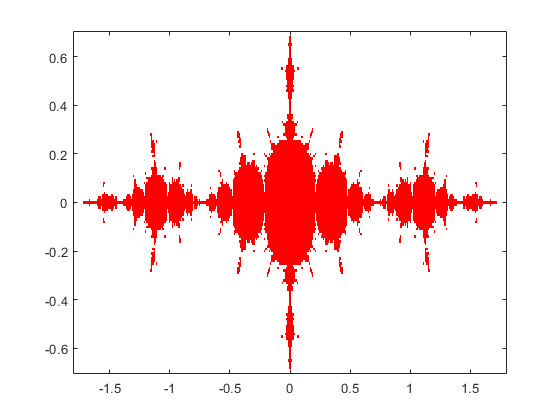

phi = inline('z^2 - 1.25');   % Define the function whose fixed points we seek.
fixpt1 = (1 + sqrt(6))/2;     % These are the fixed points.
fixpt2 = (1 - sqrt(6))/2;

colormap([1 0 0; 1 1 1]);     % Points numbered 1 (inside) will be colored red;
                              %   those numbered 2 (outside) will be colored white.
M = 2*ones(141,361);          % Initialize array of point colors to 2 (white).

for j=1:141,                  % Try initial values with imaginary parts between
  y = -.7 + (j-1)*.01;        %   -0.7 and 0.7
  for i=1:361,                % and with real parts between
    x = -1.8 + (i-1)*.01;     %   -1.8 and 1.8.
    z = x + 1i*y;             % 1i is the MATLAB symbol for sqrt(-1).
    zk = z;
    iflag1 = 0;               % iflag1 and iflag2 count the number of iterations
    iflag2 = 0;               %   when a root is within 1.e-6 of a fixed point;
    kount = 0;                % kount is the total number of iterations.

    while kount < 100 & abs(zk) < 2 & iflag1 < 5 & iflag2 < 5,
      kount = kount+1;
      zk = phi(zk);           % This is the fixed point iteration.
      err1 = abs(zk-fixpt1);  % Test for convergence to fixpt1.
      if err1 < 1.e-6,
         iflag1 = iflag1 + 1;
      else
         iflag1 = 0;
      end;
      err2 = abs(zk-fixpt2);  % Test for convergence to fixpt2.
      if err2 < 1.e-6,
        iflag2 = iflag2 + 1;
      else
        iflag2 = 0;
      end;
    end;
    if iflag1 >= 5 | iflag2 >= 5 | kount >= 100,   % If orbit is bounded, set this
      M(j,i) = 1;                                  %   point color to 1 (red).
    end;
  end;
end;

image([-1.8 1.8],[-.7 .7],M),  % This plots the results.
axis xy                        % If you don't do this, vertical axis is inverted.